# **Generalized chi-square distribution** · Getting started

The generalized chi-square variable is a quadratic form of a normal variable, or equivalently, a linear sum of independent non-central chi-square variables and a normal variable.

For function features and documentation, type:

doc gx2_to_norm_quad_params
doc norm_quad_to_gx2_params
doc gx2stat
doc gx2rnd
doc gx2char
doc gx2cdf
doc gx2pdf
doc gx2inv

Abhranil Das

Center for Perceptual Systems, University of Texas at Austin

Comments, questions, bugs to abhranil.das@utexas.edu

If you use this toolbox, please cite:

- [A method to integrate and classify normal distributions](https://arxiv.org/abs/2012.14331).

- [New methods for computing the generalized chi-square distribution.](https://arxiv.org/abs/2404.05062)

## Calculate mean and variance

% gx2 parameters
w=[1 -10 2];
k=[1 2 3];
lambda=[2 3 7];
s=5;
m=10;

[mu,v]=gx2stat(w,k,lambda,s,m)

mu = -17

v = 1771

## Generate random samples

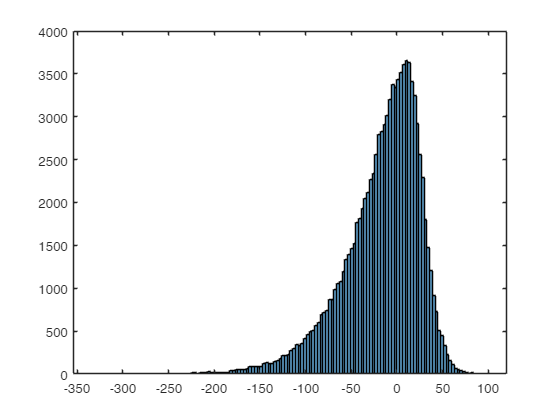

r=gx2rnd(w,k,lambda,s,m,[1 1e5]);
histogram(r)

## Calculate PDF and CDF

x=[10 25];
f=gx2pdf(x,w,k,lambda,s,m)

f =     0.0121    0.0088


p=gx2cdf(x,w,k,lambda,s,m)

p =     0.7150    0.8790


### Compute CDF with different methods

x=linspace(-200,100,50);
p_ifft=gx2cdf(x,w,k,lambda,s,m,'method','ifft');
p_imhof=gx2cdf(x,w,k,lambda,s,m,'method','imhof');
p_ray=gx2cdf(x,w,k,lambda,s,m,'method','ray','n_rays',1e4);

Using GPU. If this is slower, set gpu_batch to 0.


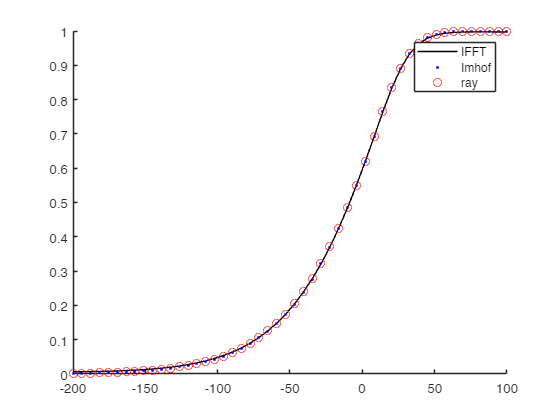

figure; hold on
plot(x,p_ifft,'-k')
plot(x,p_imhof,'.b')
plot(x,p_ray,'or')
legend('IFFT','Imhof','ray')

### Compute CDF down to tiny values

x_tail=linspace(-2e4,100,50);
p_tail_ifft=gx2cdf(x_tail,w,k,lambda,s,m,'method','ifft','span',4e8,'n_grid',1e8);
p_tail_imhof=gx2cdf(x_tail,w,k,lambda,s,m,'method','imhof','abstol',0,'reltol',1e-40);

p_tail_ray=gx2cdf(x_tail,w,k,lambda,s,m,'method','ray','n_rays',1e4);

Using GPU. If this is slower, set gpu_batch to 0.


Imhof method works better than IFFT here. Ray method is the best, and can compute values down to the double-precision limit `realmin` = $10^{-308}$.

We can also use variable precision to go down to even smaller values:

x_vpa_imhof=-2e3;
p_vpa_imhof=gx2cdf(x_vpa_imhof,w,k,lambda,s,m,'method','imhof','vpa',true,'abstol',0,'reltol',1e-50)

p_vpa_imhof = 8.9770e-36

x_vpa_ray=-2e4;
p_vpa_ray=gx2cdf(x_vpa_ray,w,k,lambda,s,m,'method','ray','n_rays',1e3,'vpa',true);

vpa(p_vpa_ray)

$$ans = 1.2059002629705238715182175830341e-466$$

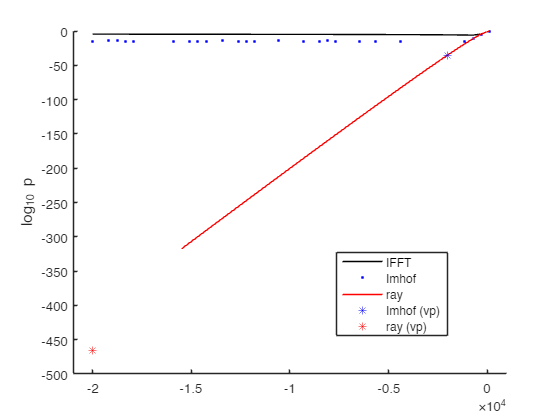


figure; hold on
plot(x_tail,log10(p_tail_ifft),'-k')
plot(x_tail,log10(p_tail_imhof),'.b')
plot(x_tail,log10(vpa(p_tail_ray)),'-r')
plot(x_vpa_imhof,log10(p_vpa_imhof),'b*')
plot(x_vpa_ray,double(log10(vpa(p_vpa_ray))),'r*')
xlim([-2.1e4 1e3])
ylabel('log_{10} p')
legend('IFFT','Imhof','ray','Imhof (vp)','ray (vp)')
legend("Position", [0.6,0.2,0.2,0.2])

### Compute PDF with different methods

f_ifft=gx2pdf(x,w,k,lambda,s,m,'method','ifft');
f_imhof=gx2pdf(x,w,k,lambda,s,m,'method','imhof');
f_ray=gx2pdf(x,w,k,lambda,s,m,'method','ray','n_rays',1e6);

Using GPU. If this is slower, set gpu_batch to 0.


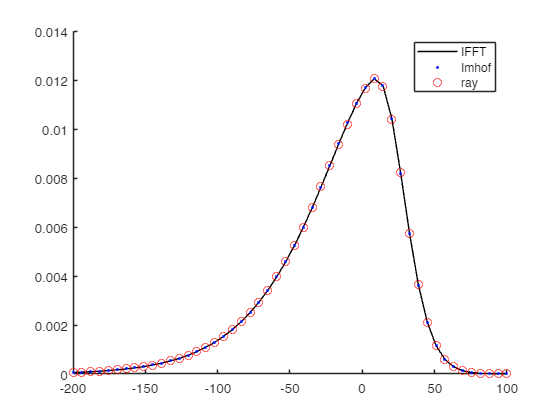

figure; hold on
plot(x,f_ifft,'-k')
plot(x,f_imhof,'.b')
plot(x,f_ray,'or')
legend('IFFT','Imhof','ray')

### Compute PDF down to tiny values

f_tail_ifft=gx2pdf(x_tail,w,k,lambda,s,m,'method','ifft','span',1e8,'n_grid',1e8);
f_tail_imhof=gx2pdf(x_tail,w,k,lambda,s,m,'method','imhof','abstol',0,'reltol',1e-2);

f_tail_ray=gx2pdf(x_tail,w,k,lambda,s,m,'method','ray','n_rays',1e4);

Using GPU. If this is slower, set gpu_batch to 0.


We can again use variable precision to go down to even smaller values:

f_vpa_imhof=gx2pdf(x_vpa_imhof,w,k,lambda,s,m,'method','imhof','vpa',true,'abstol',0,'reltol',1e-50)

f_vpa_imhof = 3.9564e-37

f_vpa_ray=gx2pdf(x_vpa_ray,w,k,lambda,s,m,'method','ray','n_rays',1e3,'vpa',true);

vpa(f_vpa_ray)

$$ans = 1.1083634123178114017821388808764e-442$$


figure; hold on
plot(x_tail,log10(f_tail_ifft),'-k')

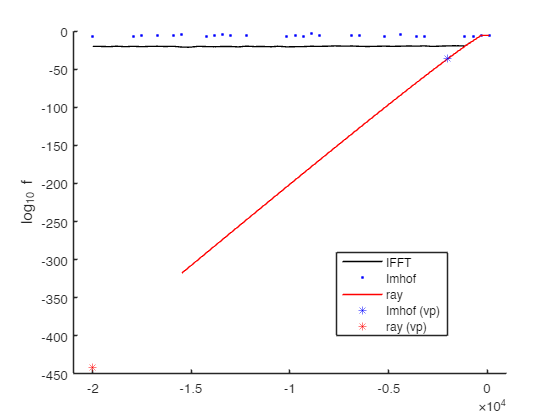

plot(x_tail,log10(f_tail_imhof),'.b')
plot(x_tail,log10(vpa(f_tail_ray)),'-r')
plot(x_vpa_imhof,log10(f_vpa_imhof),'b*')
plot(x_vpa_ray,double(log10(vpa(f_vpa_ray))),'r*')
xlim([-2.1e4 1e3])
ylabel('log_{10} f')
legend('IFFT','Imhof','ray','Imhof (vp)','ray (vp)')
legend("Position", [0.6,0.2,0.2,0.2])

### Compare computed and sampled PDF's

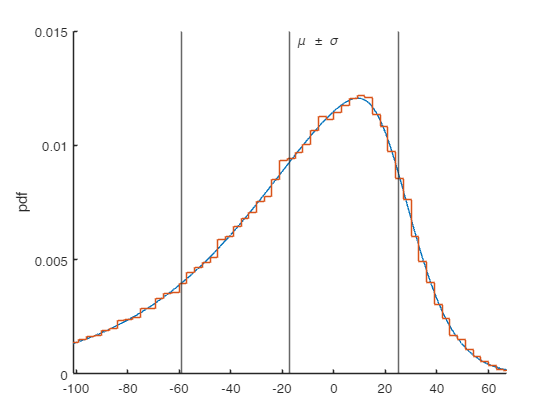

[f,~,x]=gx2pdf('full',w,k,lambda,s,m);
figure;  hold on
plot(x,f)
histogram(r,'normalization','pdf','displaystyle','stairs')
xline(mu,'-',{'\mu \pm \sigma'},'labelorientation','horizontal');
xline(mu-sqrt(v),'-'); xline(mu+sqrt(v),'-');
xlim([mu-2*sqrt(v),mu+2*sqrt(v)]); ylim([0 .015]); ylabel 'pdf'

### Compare computed and sampled CDF's

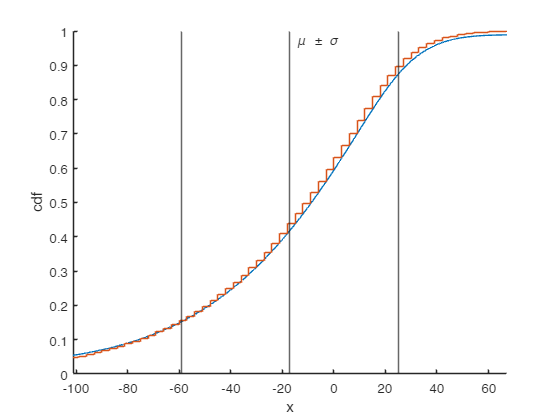

[p,~,x]=gx2cdf('full',w,k,lambda,s,m);
figure; hold on
plot(x,p)
histogram(r,'normalization','cdf','displaystyle','stairs')
xline(mu,'-',{'\mu \pm \sigma'},'labelorientation','horizontal');
xline(mu-sqrt(v),'-'); xline(mu+sqrt(v),'-');
xlim([mu-2*sqrt(v),mu+2*sqrt(v)]); ylim([0 1]); xlabel x; ylabel 'cdf'

## Compute inverse CDF

x=gx2inv([0.5 0.9],w,k,lambda,s,m)

x =    -8.7657   27.5320


Compute quantiles for cdf values of 1e-3 and 1e-2:

x=gx2inv([-3 -2],w,k,lambda,s,m)

x =  -219.2553 -149.2618


Compute quantiles for complementary cdf values of 1e-3 and 1e-2:

x=gx2inv([-3 -2],w,k,lambda,s,m,'upper')

x =    69.4899   51.0338


## Compute characteristic function

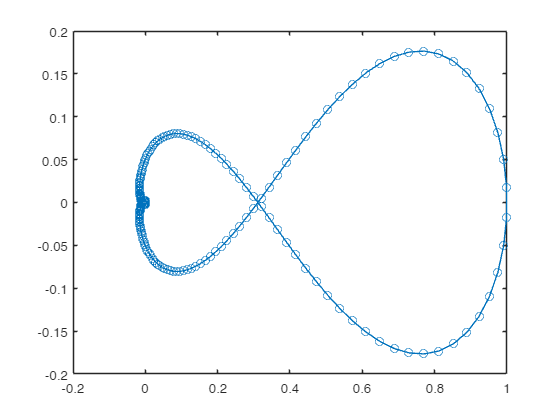

t=linspace(-1,1,1e3);
phi=gx2char(t,w,k,lambda,s,m);
figure; plot(phi,'-o')

## Distribution of quadratic form of a normal variable

Normal parameters:

mu=[5;6]; % mean
v=[2 1; 1 3]; % covariance matrix

Sample normal random vectors:

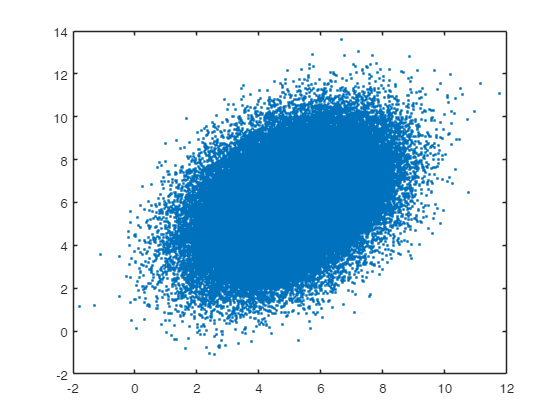

x=mvnrnd(mu,v,1e5)';
figure; plot(x(1,:),x(2,:),'.')

Quadratic form $q(\mathbf{x})=(x_1+x_2)^2-x_1-1$` = [x1;x2]'*[1 1; 1 1]*[x1;x2] + [-1;0]'*[x1;x2] -1`

quad.q2=[1 1; 1 1];
quad.q1=[-1;0];
quad.q0=-1;

Compute the quadratic form *q* for the sample of normal vectors:

q=dot(x,quad.q2*x)+quad.q1'*x+quad.q0;

Get generalized chi-square parameters corresponding to this quadratic form:

[w,k,lambda,s,m]=norm_quad_to_gx2_params(mu,v,quad)

w = 7.0000

k = 1

lambda = 16.6188

s = 0.8452

m = -1.3316

Compare the sampled and calculated distributions of *q*:

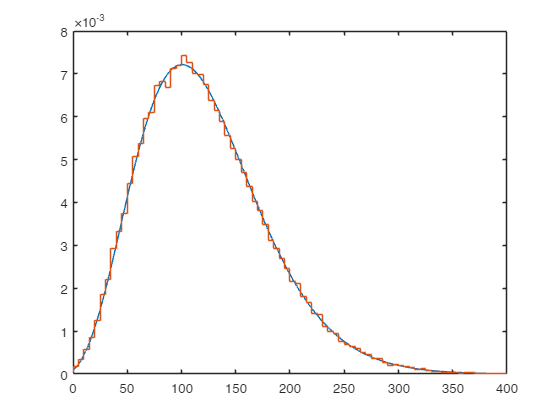

[f,~,x]=gx2pdf('full',w,k,lambda,s,m);
plot(x,f); hold on
histogram(q,'normalization','pdf','displaystyle','stairs')
xlim([0 400])

Compare the sampled and calculated means and variances:

[mu_q,v_q]=gx2stat(w,k,lambda,s,m);
[mu_q mean(q)]

ans =   122.0000  121.8059


[v_q var(q)]

ans = 1.0e+03 *

    3.3560    3.3660


Compare the sampled and calculated probabilities $p(q(\mathbf{x})<50)$:

mean(q<50)

ans = 0.0863

gx2cdf(50,w,k,lambda,s,m)

ans = 0.0856

Find a canonical quadratic form of a standard multinormal corresponding to these generalized chi-square parameters:

quad=gx2_to_norm_quad_params(w,k,lambda,s,m)

quad = struct with fields:
    q2: [2×2 double]
    q1: [2×1 double]
    q0: 115
